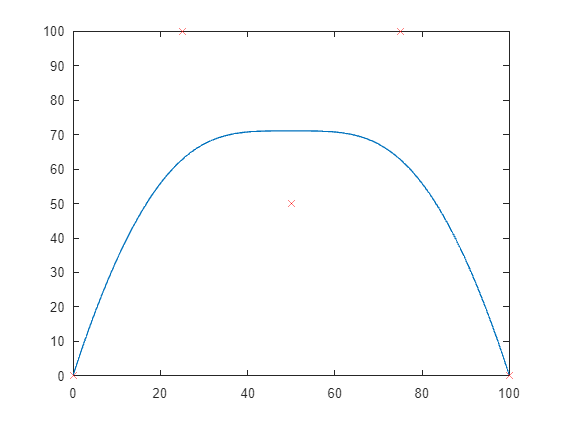

%WORKING INTEGRATOR P-V-A-V-P
%some error calculation at end

order = 7;
targets = [0,0; 25,100; 50,50; 75,100; 100,0];
CP = points(targets, order);
CPx = CP(:,1);
CPy = CP(:,2);
%Curve Parameters
pmin = 0;
pmax = 5;
pstep = 0.028;
%Knot Vector
knot = knotvect(CP, order, pmin, pmax, pstep);
ksz = size(knot);
validpmin = knot(1, order);
validpmax = knot(1, (ksz(1,2)-order+1));
NK2MAT = [];
NK3MAT = [];
NK4MAT = [];
NK5MAT = [];
NK6MAT = [];
NK7MAT = [];
pM1 = [];
pM2 = [];
pM3 = [];
pM4 = [];
pM5 = [];
pM6 = [];
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
PMagMAT = absBS(PosMAT);
order = 6;
VCP = DCP(CP, knot, order);
vknot = Dkn(knot);
VelMAT = evaluate(VCP, pmin, pstep, pmax, validpmin, validpmax, vknot, order);
VMagMAT = absBS(VelMAT);
order = 5;
ACP = DCP(VCP, vknot, order);
aknot = Dkn(vknot);
AccMAT = evaluate(ACP, pmin, pstep, pmax, validpmin, validpmax, aknot, order);
AMagMAT = absBS(AccMAT);
plot(PosMAT(:,1),PosMAT(:,2))
hold on
scatter(CPx, CPy, 60, 'red', 'X')
hold off

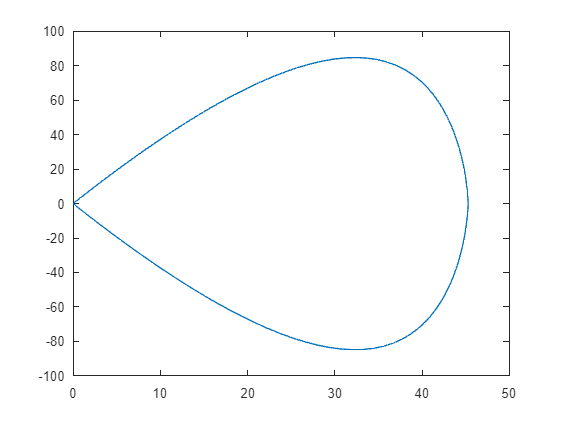

plot(VelMAT(:,1),VelMAT(:,2))

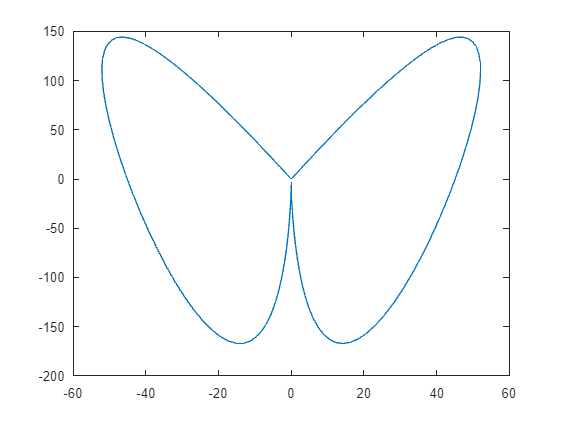

plot(AccMAT(:,1),AccMAT(:,2))

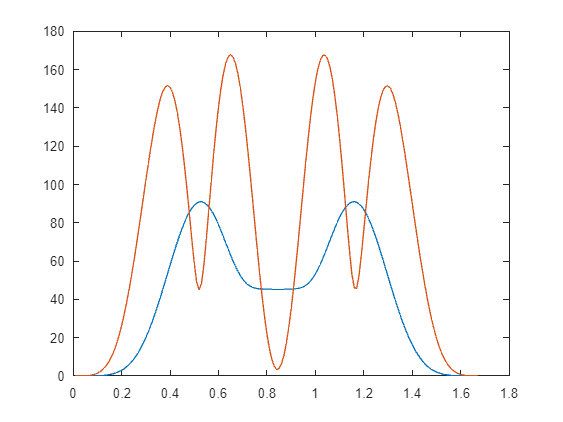

plot(VMagMAT(:,1)/100, VMagMAT(:,2))
hold on
plot(AMagMAT(:,1)/100, AMagMAT(:,2))
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
knot

knot =          0    0.0280    0.0560    0.0840    0.1120    0.1400    0.1680    0.5556    1.1111    1.6667    2.2222    2.7778    3.3333    3.8889    4.4444    4.8320    4.8600    4.8880    4.9160    4.9440    4.9720    5.0000


vknot

vknot =     0.0280    0.0560    0.0840    0.1120    0.1400    0.1680    0.5556    1.1111    1.6667    2.2222    2.7778    3.3333    3.8889    4.4444    4.8320    4.8600    4.8880    4.9160    4.9440    4.9720


aknot

aknot =     0.0560    0.0840    0.1120    0.1400    0.1680    0.5556    1.1111    1.6667    2.2222    2.7778    3.3333    3.8889    4.4444    4.8320    4.8600    4.8880    4.9160    4.9440


vknot = Ikn(aknot, pstep)

vknot =     0.0280    0.0560    0.0840    0.1120    0.1400    0.1680    0.5556    1.1111    1.6667    2.2222    2.7778    3.3333    3.8889    4.4444    4.8320    4.8600    4.8880    4.9160    4.9440    4.9720


knot = Ikn(vknot, pstep)

knot =          0    0.0280    0.0560    0.0840    0.1120    0.1400    0.1680    0.5556    1.1111    1.6667    2.2222    2.7778    3.3333    3.8889    4.4444    4.8320    4.8600    4.8880    4.9160    4.9440    4.9720    5.0000


VCP

VCP =          0         0
         0         0
         0         0
         0         0
         0         0
   47.3884  189.5535
   45.0000  -90.0000
   45.0000   90.0000
   47.3884 -189.5535
         0         0


ACP

ACP =          0         0
         0         0
         0         0
         0         0
   90.7901  363.1602
   -4.2991 -503.1963
   -0.0000  324.0000
    4.2991 -503.1963
  -90.7901  363.1602
         0         0


VCP = ICP(ACP, vknot, 5, [0,0])

VCP =          0         0
         0         0
         0         0
         0         0
         0         0
   47.3884  189.5535
   45.0000  -90.0000
   45.0000   90.0000
   47.3884 -189.5535
         0   -0.0000


order = order + 1;
iMAT = evaluate(VCP, pmin, pstep, pmax, validpmin, validpmax, vknot, order);
iMagMAT = absBS(iMAT);
plot(iMAT(:,1), iMAT(:,2))

CP = ICP(VCP, knot, order, [0,0])

CP =          0         0
         0         0
         0         0
         0         0
         0         0
         0         0
   25.0000  100.0000
   50.0000   50.0000
   75.0000  100.0000
  100.0000   -0.0000


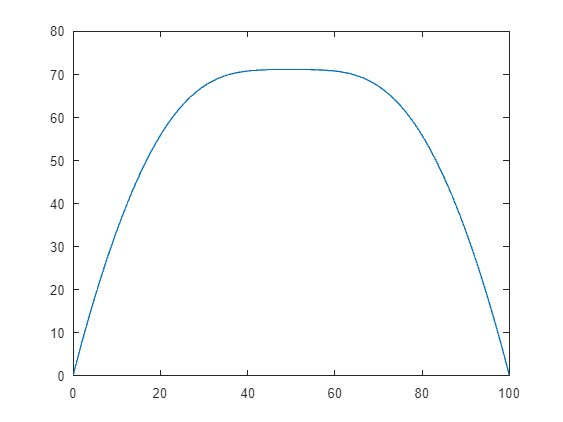

order = order + 1;
i2MAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
i2MagMAT = absBS(i2MAT);
plot(i2MAT(:,1),i2MAT(:,2))

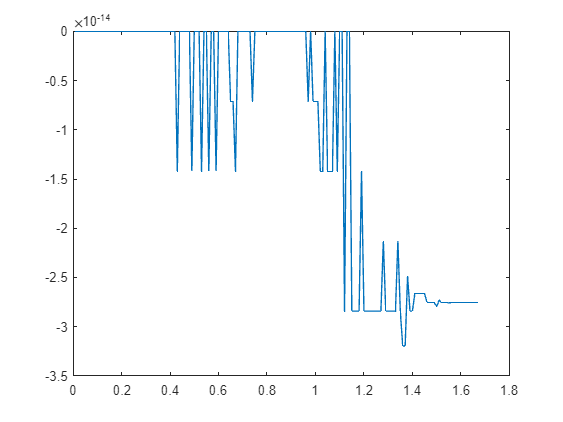

plot(iMagMAT(:,1)/100, VMagMAT(:,2)-iMagMAT(:,2))

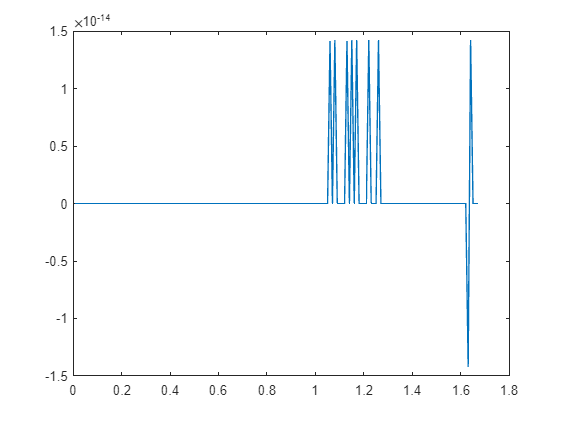

plot(i2MagMAT(:,1)/100, PMagMAT(:,2)-i2MagMAT(:,2))

function IP = ICP(CP, knot, k, c)
    CPx = CP(:,1);
    CPy = CP(:,2);
    n = length(CP);
    IP1 = c;
    IP = IP1;
    for i = 1:1:n
        xhold = CPx(i);
        yhold = CPy(i);
        IP2x = xhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,1);
        IP2y = yhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,2);
        IP = [IP; IP2x, IP2y];
        IP1 = [IP2x, IP2y];
    end
end
function Iknot = Ikn(knot, pstep)
    n = length(knot);
    Iknot = knot(1)-pstep;
    for i = 1:1:n
        Iknot = [Iknot, knot(i)];
    end
    Iknot = [Iknot, knot(n)+pstep];
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function pMAT = pMAT(p,knot,k)
    N = length(knot);
    pMAT = [];
    for i = 1:1:N-k
        pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
        pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
        Head = zeros(i-1,1);
        Foot = zeros(N-k-i,1);
        pvect = [Head; pconst1; pconst2; Foot];
        pMAT = [pMAT, pvect];
    end
end
function CP = points(targets, order)
    P = height(targets);
    rep = order - 1;
    CP = [];
    hold = [targets(1,1), targets(1,2)];
    for n = 1:1:rep
        CP = [CP; hold];
    end
    for i = 2:1:P-1
        hold = [targets(i,1), targets(i,2)];
        CP = [CP; hold];
    end
    hold = [targets(P,1), targets(P,2)];
    for k = 1:1:rep
        CP = [CP; hold];
    end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
    sz = size(CP);
    P = sz(1,1);
    K = P + order;
    Knot = pmin;
    for i = 1:1:order-1
        Knot = [Knot, pmin+i*pstep];
    end
    for i = 1:1:K-2*order
        Knot = [Knot, i*pmax/(K-2*order+1)];
    end
    for i = 1:1:order
        Knot = [Knot, pmax-(order-i)*pstep];
    end
end
function NK1MAT = NK1MAT(p, knot)
    N = length(knot);
    NK1MAT = [];
    for i = 1:1:N-1
        lowkn = knot(i);
        highkn = knot(i+1);
        if lowkn<=p && p<highkn
            NK1MAT = [NK1MAT, 1];
        else
            NK1MAT = [NK1MAT, 0];
        end
    end
end

function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
    BSplineMAT = [];
    for p = pmin:pstep:pmax
        if p >= validpmin
            if p<=validpmax
                k = 2;
                NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                k = 3;
                NK3MAT = NK2MAT*pMAT(p, knot, k);
                k = 4;
                if order < k
                    Pos = NK3MAT*CP;
                else
                    NK4MAT = NK3MAT*pMAT(p, knot, k);
                    k = 5;
                    if order < k
                        Pos = NK4MAT*CP;
                    else
                        NK5MAT = NK4MAT*pMAT(p, knot, k);
                        k = 6;
                        if order < k
                            Pos = NK5MAT*CP;
                        else
                            NK6MAT = NK5MAT*pMAT(p, knot, k);
                            k = 7;
                            if order < k
                                Pos = NK6MAT*CP;
                            else
                                NK7MAT = NK6MAT*pMAT(p, knot, k);
                                Pos = NK7MAT*CP;
                            end
                        end
                    end
                end
                BSplineMAT = [BSplineMAT; Pos];
            end
        end
    end
end

function DP = DCP(CP, knot, k)
    n = length(CP);
    DP = [];
    for i = 1:1:n-1
        I = i+1;
        P1 = [CP(i,1),CP(i,2)];
        P2 = [CP(i+1,1),CP(i+1,2)];
        DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
        DP = [DP; DPnew];
    end
end
function DKnot = Dkn(knot)
    N = length(knot);
    DKnot = [];
    for i = 1:1:N-2
        DKnew = knot(i+1);
        DKnot = [DKnot, DKnew];
    end
end
function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end
